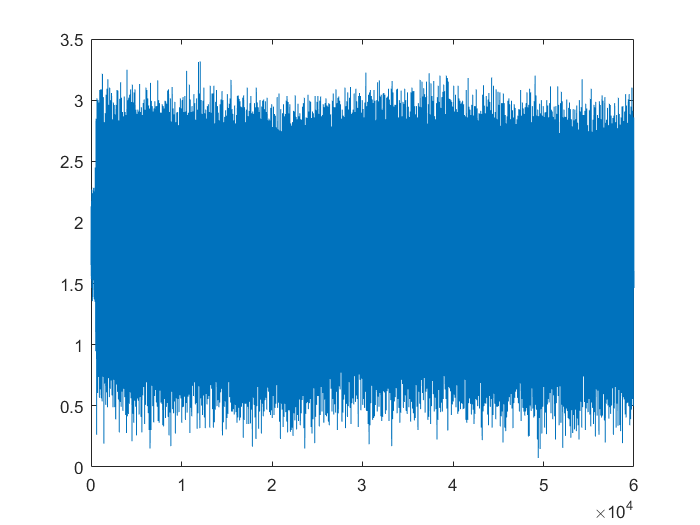

% clear
load("data/daq_sin.mat");
y = data.y(1:end);
plot(y)

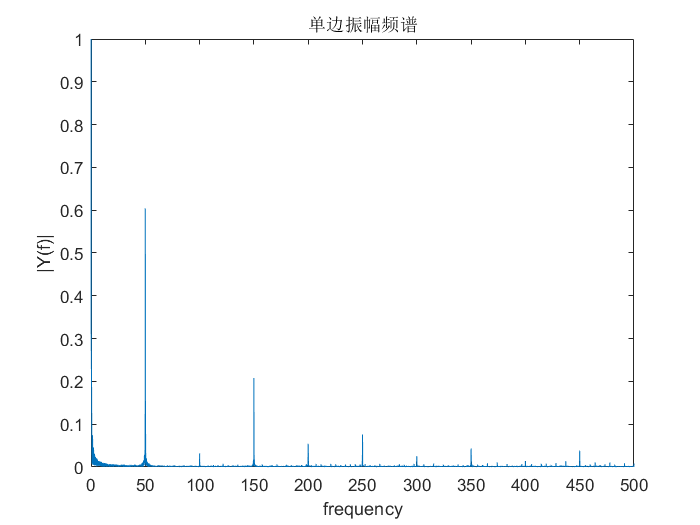


Fs = 5000;

[f, p] = fftFunc(Fs, length(y), y);

plot(f, p)
title("单边振幅频谱")
xlabel('frequency')
ylabel('|Y(f)|')
xlim([0, 500])
ylim([0, 1])

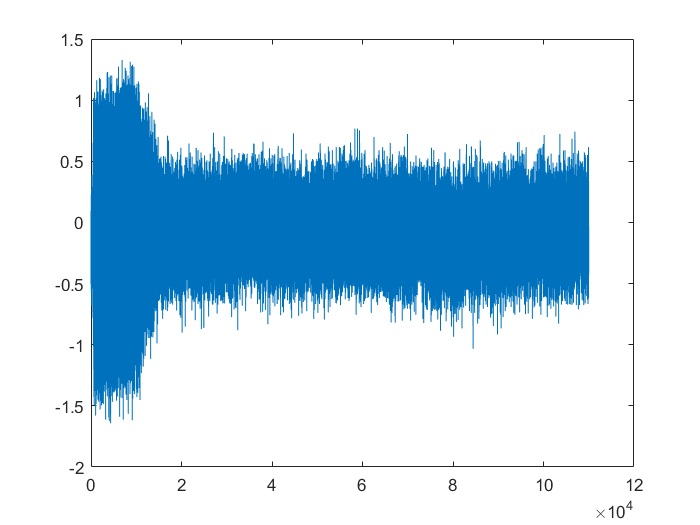

% clear
load("bandpass50.mat")
load("data/daq_wrapper.mat");
y = data.y(1:end);
plot(y)

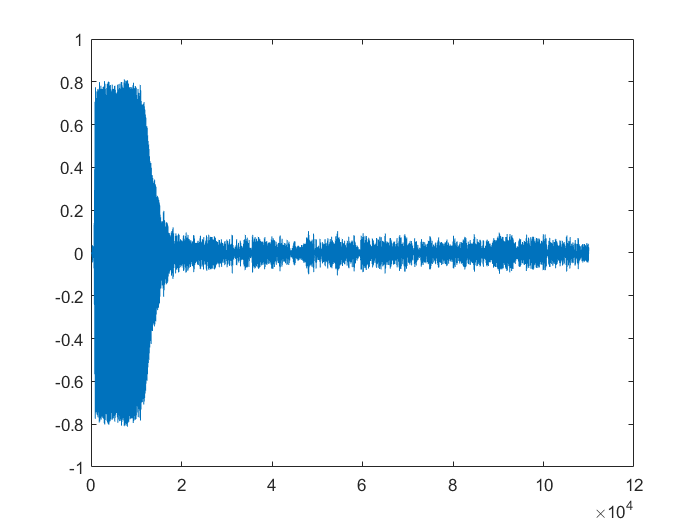


plot(filter(bandpass50,y))

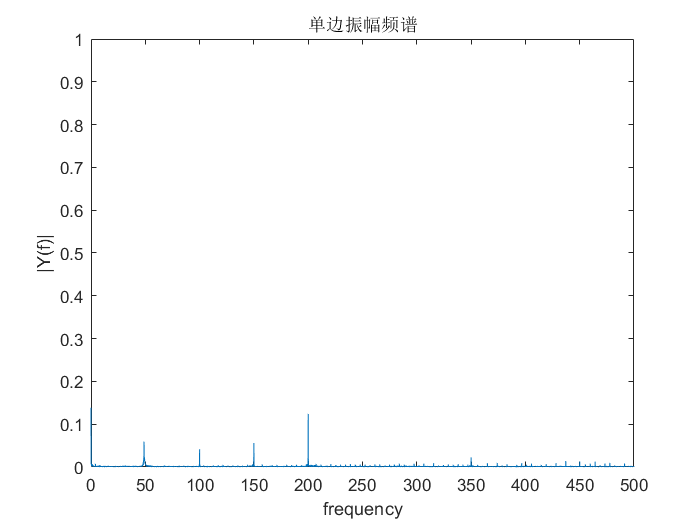

Fs = 5000;

y = data.y(10000:end);

[f, p] = fftFunc(Fs, length(y), y);

plot(f, p)
title("单边振幅频谱")
xlabel('frequency')
ylabel('|Y(f)|')
xlim([0, 500])
ylim([0, 1])

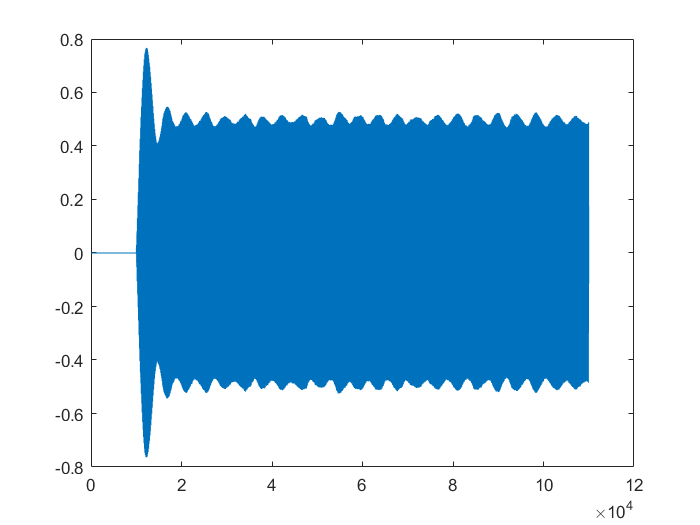




u = data.u(1:end);
plot(u)

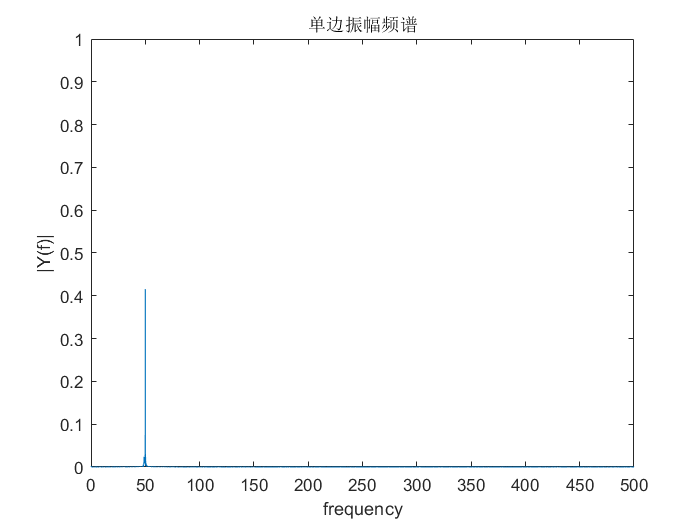

Fs = 5000;

[f, p] = fftFunc(Fs, length(u), u);

plot(f, p)
title("单边振幅频谱")
xlabel('frequency')
ylabel('|Y(f)|')
xlim([0, 500])
ylim([0, 1])

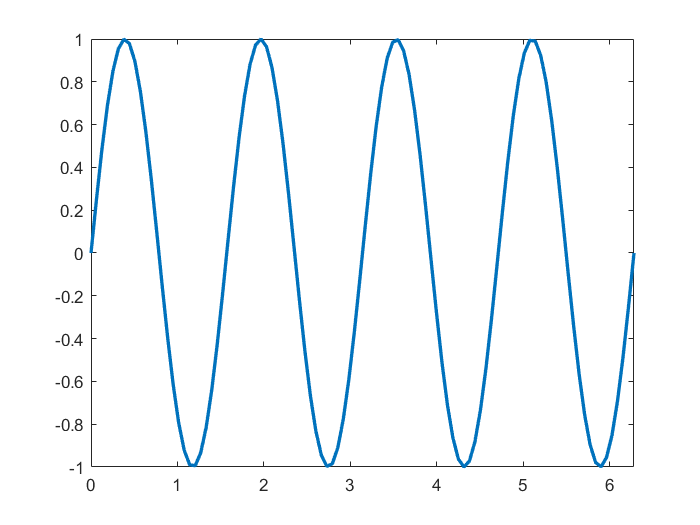


fig = figure;
x = linspace(0, 2*pi, 100);
im = cell(1, 20);
for i = 1:20
    yn = y(i:i);
    plot(x, y, 'LineWidth', 2);
    xlim([0, 2*pi]);
    pause(0.05);
    % 注释下面两句话可以看到动态输出
%     frame = getframe(fig);
%     im{i} = frame2im(frame);
end

% % 下面是保存成 gif
% filename = 'D:\MyPrograms\DataSet\程序运行截图\Matlab_2_7_6_Curve_Animation1.gif'; 
% for idx = 1:20
%     % 制作gif文件，图像必须是index索引图像
%     [A, map] = rgb2ind(im{idx}, 256);
%     if idx == 1
%         imwrite(A, map, filename, 'gif', 'LoopCount', Inf, 'DelayTime', 0.3);
%     else
%         imwrite(A, map, filename, 'gif', 'WriteMode', 'append', 'DelayTime', 0.3);
%     end
% end

function [f, p] = fftFunc(Fs, L, y)
T= 1/Fs; %采样时间
t = (0:L-1)*T; %时间向量
NFFT = 2^nextpow2(L);
Y = fft(y,NFFT)/L;
f = Fs/2*linspace(0,1,NFFT/2);
p = 2*abs(Y(1:NFFT/2));
end